# 3. Software for data acquisition and control

clear;
Ts = 0.01; %(s) define the sampling interval
t = (0:Ts:8)'; %(s) define the discrete time span
u = 1*(t-2>0); %(V) unit step u(t-2s) (V)
y = simOpenLoop(t,u,Ts); % simulate open loop response
save('./DATA/3_SoftwareDataAcquisition/stepResponse.mat','t','u','Ts','y');

*Q2. Write a (very short) report about open-loop experiments and data collection *

*The report must include:*

*• **Comment on the motor operation. Explain in particular why their angular position never stabilizes when its command signal is constant in the open loop conditions described.*

A DC motor such as the one being used in this lab is well modelled by an integrator cascaded with a second order low pass filter, i.e., with a transfer function of the form

 $H(s) = \frac{K\omega_n^2}{s(s^2+2 \xi \omega_n s+\omega_n^2)}$,

thus for a constant non-zero input signal it beahaves as an integrator. 

*• **Show the step response. Include in the report graphics documenting the step response.*

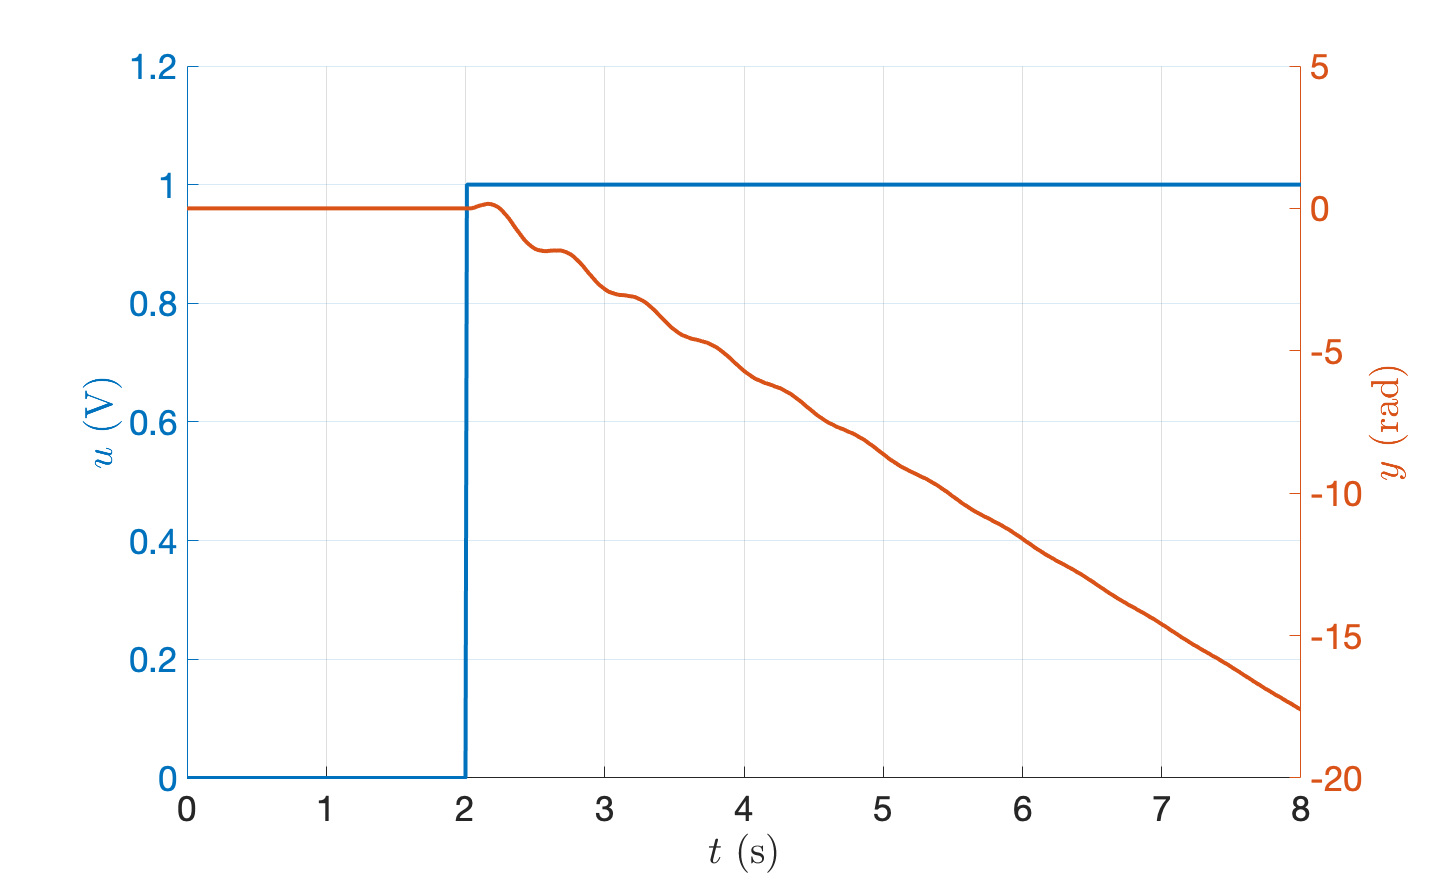

figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
set(gca,'FontSize',35);
ax = gca;
ax.XGrid = 'on';
ax.YGrid = 'on';
yyaxis left;
plot(t,u,'Linewidth',4);
ylabel('$u$ (V)','Interpreter','latex');
ylim([0 1.2]);
yyaxis right;
plot(t,y,'Linewidth',4);
ylabel('$y$ (rad)','Interpreter','latex');
xlabel('$t$ (s)','Interpreter','latex');
saveas(gcf,'./DATA/3_SoftwareDataAcquisition/stepResponse.fig');
saveas(gcf,'./DATA/3_SoftwareDataAcquisition/stepResponse.png');
hold off;

As expected the motor behaves as an integrator for a non-zero constant input. First, note that the gain $K$is negative. Second, the oscilation seen in the step response is not due to the poles of the low pass filter used to model the DC motor, it is the result of the fundamental oscilating mode of the flexible bar. The frequency of the DC motor poles is significantly greater than the fundamental frequency of the flexibal bar, and connot be distiguished in this figure.